Second attempt at calculating V(q), had numerical integration errors the first time. 

eps = 1;
h = 0.2;
z = linspace(0, 1.5, 100)';

Plots

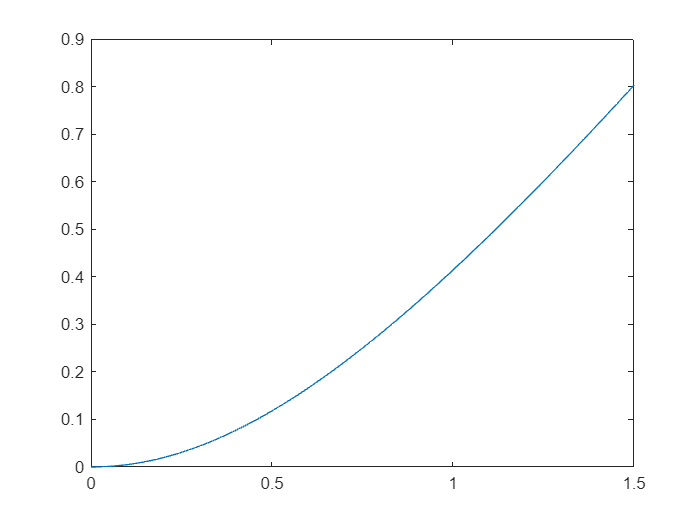

plot(z, sigmanorm(z, eps));

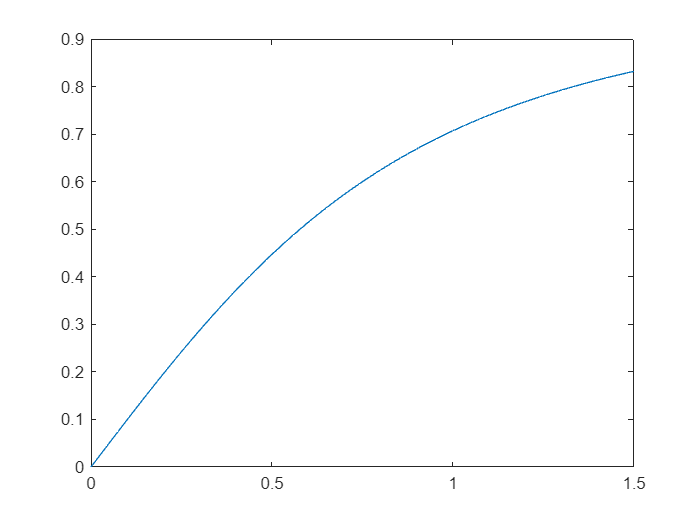

plot(z, sigma(z, eps));

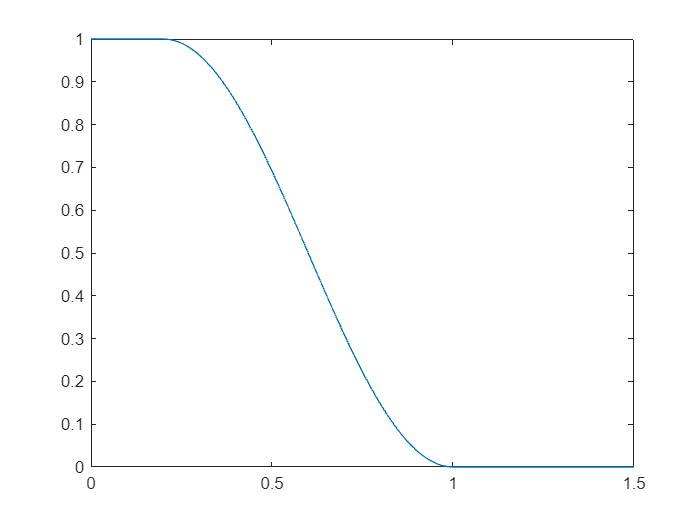

plot(z, bump(z, h));

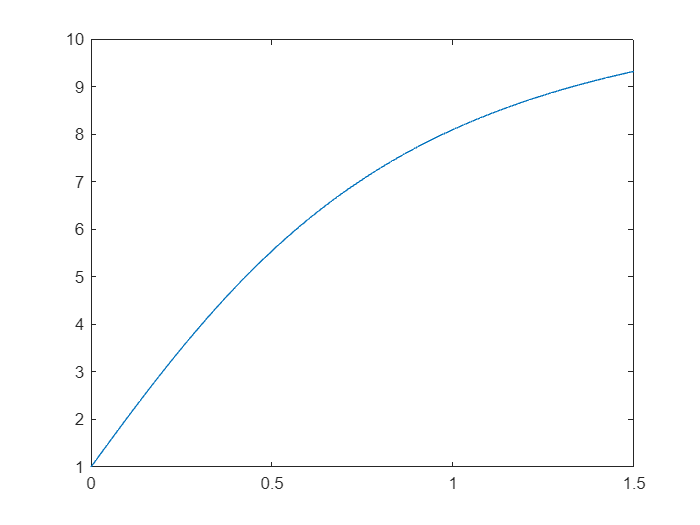

a = 11;
b = 10;
c = abs(a - b) / sqrt(4*a*b);
plot(z, phi(z, a, b, c, eps));

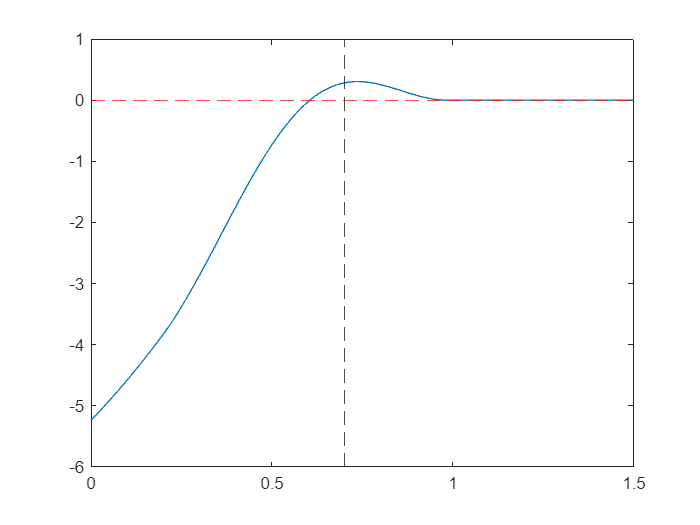

d = 0.7;
r = 0.98;
plot(z, bump(z/r, h).*phi(z-d, a, b, c, eps));
hold on
yline(0, 'r--');
xline(d, 'k--');
hold off

% params = {a, b, c, eps, h, d, r};
z = 1;
psialpha(z, @phialpha, d, a, b, c, eps, h, d, r)

ans = 0.0479

r_alpha = sigmanorm(r, epsilon);
d_alpha = sigmanorm(d, epsilon);
n_ij = sigma(q(2,:) - q(5,:), epsilon);
u_grad = sum(phialpha(sigmanorm(q(2,:)-q(5,:), epsilon)/100, a, b, c, epsilon, h, d_alpha/10, r_alpha/10) .* n_ij, 1)

u_grad =     0.2480    0.6929


% plot(z, psialpha(z, @phialpha, d, a, b, c, eps, h, d, r));

Functions

function y = sigmanorm(x, eps)
    y = 1/eps .* (sqrt(1 + eps*x.^2) - 1);
end

function y = sigma(x, eps)
    y = x ./ (1  + eps*sigmanorm(x, eps));
end

function  y = bump(x, h)
    y = zeros(size(x));
    y(x >= 0 & x < h) = 1;
    y(x >= h & x < 1) = 0.5 * (1 + cos(pi * (x(x >= h & x < 1) - h) / (1 - h)));
    y(x >= 1) = 0;
end
    
function y = phi(x, a, b, c, eps)
    y = 1/2 * ((a+b)*sigma(x+c, eps) + (a-b));
end

function y = phialpha(x, a, b, c, eps, h, d, r)
    y = bump(x/r, h).*phi(x-d, a, b, c, eps);
end

function y = psialpha(x, phialpha, d, varargin)
    y = arrayfun(@(xi) integral(@(s) phialpha(s, varargin{:}), d, xi), x);
end